# Problem #1

[x, A, b] = problem_11_3();

% (a)
disp('11.3 (a)')

11.3 (a)


x(:, 1)

ans =    0.999999996787553
   0.000000350916732
  -8.000003028795119
  -0.000077893877909
  10.668084035612900
  -0.009615585352545
  -5.654480747960067
  -0.068885958631546
   1.693354534665567
   0.001461547101732



% (b)
disp('11.3 (b)')

11.3 (b)


x(:, 2)

ans =    1.000000001037689
  -0.000000426525960
  -7.999981225479934
  -0.000317425649726
  10.669411140597621
  -0.013695419352547
  -5.647518455098814
  -0.074362540368604
   1.692331412818159
   0.007068808893883



% (d)
disp('11.3 (d)')

11.3 (d)


x(:, 4)

ans =    1.000000000996605
  -0.000000422742859
  -7.999981235690551
  -0.000318763171777
  10.669430795484192
  -0.013820286242889
  -5.647075632082337
  -0.075316015937716
   1.693606953829228
   0.006032115717738



% (e)
disp('11.3 (e)')

11.3 (e)


x(:, 5)

ans =    1.000000000996607
  -0.000000422743364
  -7.999981235676154
  -0.000318763346323
  10.669430796641096
  -0.013820290914619
  -5.647075619959385
  -0.075316036589419
   1.693606976803618
   0.006032099645104



% (f)
disp('11.3 (f)')

11.3 (f)


x(:, 6)

ans =    1.000000000996607
  -0.000000422742875
  -7.999981235690126
  -0.000318763177247
  10.669430795521089
  -0.013820286388562
  -5.647075631726875
  -0.075316016484857
   1.693606954355020
   0.006032115417650


## Problem #2

Do 11.3c

% (c)
disp('11.3 (c)')

11.3 (c)


x(:, 3)

ans =    1.000000000996608
  -0.000000422743110
  -7.999981235683617
  -0.000318763250131
  10.669430795965791
  -0.013820288049901
  -5.647075627723565
  -0.075316022816632
   1.693606960867836
   0.006032111236744


## Problem #3

plot(x)
xlabel('t')
ylabel('p(x)')
label = 'abcdef'

label = 'abcdef'

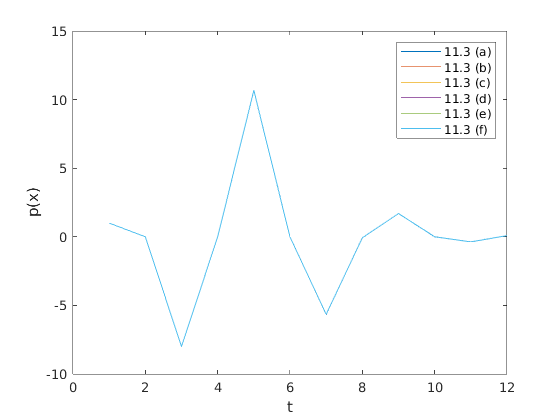

for ii = 1:length(label)
    leg{ii} = ['11.3 (', label(ii), ')'];
end
legend(leg);

sum(diff(x))

ans =   -0.912904130256858  -0.911868840790748  -0.911959424664688  -0.911959424418601  -0.911959425534252  -0.911959424428643


## Problem #4

Truncated svd with p = 6, 8, 10 We see that singular values decay sharply after p = 6 so that singular values 7-10 don't add much to the reconstruction.

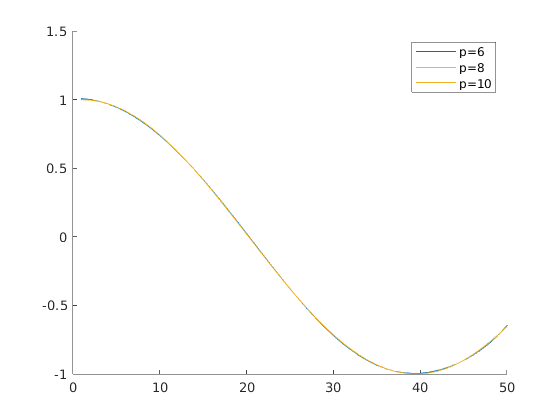

% Compute reduced SVD
[U, S, V] = svd(A, 'econ');

figure
hold on
for p = [6, 8, 10]
    c_svd = truncated_svd(U, S, V, b, p);
    plot(A * c_svd)
end
legend({'p=6', 'p=8', 'p=10'})

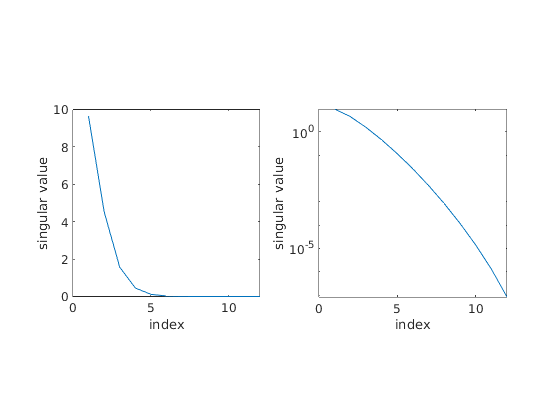


figure
subplot(1, 2, 1)
plot(diag(S))
axis square

xlabel('index')
ylabel('singular value')
subplot(1, 2, 2)
plot(diag(S))
axis square
set(gca, 'YScale', 'log')
xlabel('index')
ylabel('singular value')

## Problem #5

Randomized projection

m = 10000;
n = 100;
t = linspace(0, 1, m);
A = vander(t);
A = A(:, 1:n);

tic;
svd(A, 'econ');
t_svd = toc;

k = 10; p = 5;
tic;
rsvd(A, k, p);
t_rsvd = toc;

disp(['rsvd is ', num2str(round(t_svd / t_rsvd, 2)) 'x faster than svd.'])

rsvd is 1.73x faster than svd.


function [U,S,V] = rsvd(A, K, P)
    %-------------------------------------------------------------------------------------
    % random SVD
    % Extremely fast computation of the truncated Singular Value Decomposition, using
    % randomized algorithms as described in Halko et al. 'finding structure with randomness
    %
    % usage : 
    %
    %  input:
    %  * A : matrix whose SVD we want
    %  * K : number of components to keep
    %
    %  output:
    %  * U,S,V : classical output as the builtin svd matlab function
    %-------------------------------------------------------------------------------------
    % Antoine Liutkus  (c) Inria 2014
    [M,N] = size(A);

    if nargin < 3
        P = min(2*K,N);
    end
    X = randn(N,P);
    Y = A*X;
    W1 = orth(Y);
    B = W1'*A;
    [W2,S,V] = svd(B,'econ');
    U = W1*W2;
    K=min(K,size(U,2));
    U = U(:,1:K);
    S = S(1:K,1:K);
    V=V(:,1:K);
end % rsvd
function c = truncated_svd(U, S, V, b, p)
    c = zeros(size(U, 2), 1);
    for ii = 1:p
        c = c + (1 / S(ii, ii)) * V(:, ii) * U(:, ii)' * b;
    end
end % truncated_svd

function [x, A, b] = problem_11_3()
    format long;
    m = 50; n = 12;
    t = linspace(0,1,m);
    A = fliplr(vander(t));
    A = A(:,1:12);
    b = cos(4*t)';
    %(a) Normal equations
    R = chol(A'*A);
    x1 = R\(R'\(A'*b));
    %(b) QR factorization computed by mgs
    [Q, R] = mgs(A);
    x2 = R\(Q'*b);
    %(c) QR factorization computed by house
    [W, R] = house(A);
    Q = formQ(W);
    Q = Q(:,1:n);
    x3 = R\(Q'*b);
    %(d) QR factorization
    [Q, R] = qr(A);
    x4 = R\(Q'*b);
    %(e) x = A\b in MATLAB
    x5 = A\b;
    %(f) SVD
    [U, S, V] = svd(A,0);
    x6 = V*(S\(U'*b));
    x = [x1, x2, x3, x4, x5, x6];
end %poly_apprx

function [W, R] = house(A)
    % Householder triangularization
    [m, n] = size(A);
    if (m<n)
        error('number of rows cannot be smaller than number of columns.');
    end
    
    W = zeros(m,n);
    
    for k=1:n
        x = A(k:m, k);
        if (x(1)>=0)
        sgn = 1;
        else
        sgn = -1;
        end
        v = sgn*norm(x,2)*eye(m-k+1,1)+x;
        v = v/norm(v,2);
        A(k:m, k:n) = A(k:m, k:n) - 2*(v*v')*A(k:m, k:n);
        W(k:m,k) = v;
    end

    R = A(1:n,:);
end % house


function [Q, R] = mgs(A)
    % Modified Gram-Schmidt
    [m, n] = size(A);

    if (m<n)
        error('number of rows must be no less than number of columns.');
    end

    Q = zeros(m,n);
    R = zeros(n,n);
    for i=1:n
        Q(:, i) = A(:, i);
    end

    for i=1:n
        R(i,i) = norm(Q(:,i),2);
        Q(:,i) = Q(:,i)/R(i,i);
        for j = (i+1):n
            R(i,j) = Q(:,i)'*Q(:,j);
            Q(:,j) = Q(:,j) - R(i,j)*Q(:,i);
        end
    end

end % function

function Q = formQ(W)
    [m, n] = size(W);
    
    if (m<n)
        error('number of rows cannot be smaller than number of columns.');
    end
    
    Q = eye(m,m);
    
    for k = 1:m
        Q(:,k) = formQx(W,Q(:,k));
    end
end %formQ

function y = formQx(W, x)
    [m, n] = size(W);

    if (m<n)
        error('number of rows cannot be smaller than number of columns.');
    end

    if (~isvector(x))
        error('x must be a vector.');
    elseif (length(x) ~= m)
        error('length of x must agree with the number of rows for W.');
    end

    for k = n:-1:1
        x(k:m) = x(k:m)-2*W(k:m,k)*(W(k:m,k)'*x(k:m));
    end
    y = x;
end %formQx